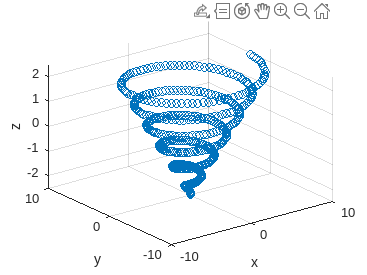


% Utilizing Gaussian Mixture Model Fitting
% Approach: go through a spiral trajectory to collect points to fit
% and then fit the Gaussian. 

% number of points
num_points = 500;

% Generate a polar spiral
theta = linspace(0, 12 * pi, num_points); % Angles from 0 to 4*pi
z = linspace(-2.5, 2.5, num_points);
a = 0.2; % Constant determining the tightness of the spiral
r = a * theta;

% Convert polar coordinates to Cartesian coordinates
x = r .* cos(theta);
y = r .* sin(theta);

opts = optimset('Display','off');
l = 1000;
num_ones = l;
res = ones(1,l);
for i = 1:l
%initial_point = [-1;1;0];
%initial_point = rand(4,1)*-1;
focus_guess = rand(1,1)*2; %1.5;
% [p0; A0; a0; b0]
%p0 = [0.3, 0.7, -0.2  0];
p0 = rand(1,4)*-1;
A0 = [0.8, 0.3,  0.1, 0.3];
a0 = [0.8, 1.7,  1.0, 0.5];
b0 = [0.0, 2.0,  4.0, 4.2];
c0 = [3, focus_guess, 0,0];
initial_param = [p0; A0; a0; b0;c0];

xyz = [x+initial_point(1);
       y+initial_point(2);
       z+initial_point(3)];

P = lsqcurvefit(@I3_param,initial_param,xyz,I3(xyz),[],[],[],[],[],[],[],opts);

if abs(I3([0 0 -1].') - I3(P(1,1:3).')) > 0.1
   res(1,i) = 0;
   num_ones = num_ones - 1;
end


end

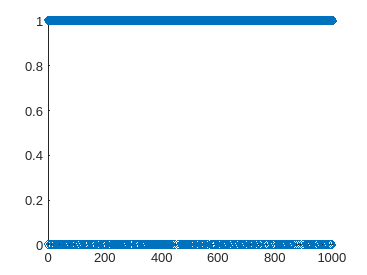


scatter(1:l,res);

scatter3(x,y,z)
xlabel("x")
ylabel("y")
zlabel("z")

num_ones

num_ones = 699


p

function intensity = I3(p)
x = p(1,:);
y = p(2,:);
z = p(3,:);
intensity = 1.0*exp(-0.5.*(x.^2 + y.^2)) + ...
            0.5*exp(-1.*((x.^2+y.^2).^(1/2)-2).^2) + ...
            0.4*exp(-1.5.*((x.^2+y.^2).^(1/2)-2*2).^2) + ...
            0.2*exp(-1.8.*((x.^2+y.^2).^(1/2)-2*2.1).^2);
% focus is at z = 1
focus = 1;
% Accounting for z dependence
intensity = intensity .* exp(-2*(z-focus).^2);
end

function generic_intensity = I3_param(param,p)
generic_intensity = 0;
x = p(1,:);
y = p(2,:);
z = p(3,:);
x0 = param(1,1);
y0 = param(1,2);
z0 = param(1,3);
c0 = param(5,1);
focus0 = param(5,2);
for i = 1:4
    Ai = param(2,i);
    ai = param(3,i);
    bi = param(4,i);
    term = Ai*exp(-ai.*(((x-x0).^2+(y-y0).^2).^(1/2)-bi).^2);
    generic_intensity = generic_intensity + term .* exp(-c0*((z-z0)-focus0).^2);
end
% % 
% focus = 1;
% generic_intensity = A1*exp(-0.25.*((x-x0).^2 + (y-y0).^2)) + ...
%                     A2*exp(-1.*(((x-x0).^2+(y-y0).^2).^(1/2)-2*2).^2) + ...
%                     A3*exp(-2.*(((x-x0).^2+(y-y0).^2).^(1/2)-2*4).^2) + ...
%                     A4*exp(-4.*(((x-x0).^2+(y-y0).^2).^(1/2)-2*6).^2);
% % Accounting for z dependence
% generic_intensity = generic_intensity .* exp(-0.5*((z-z0)-focus).^2);
end